# AAE 340 HW3 

## Tomoki Koike 

#### A particle, P, of mass m slides in a smooth tube whcih rotates at a constant rate, $\frac{d\theta }{\mathrm{dt}}$. Assume the unstretched spring length, $l_o$, is zero. The spring has a constant of $k$and the damper has a damping coefficient of $c$.

#### The EOM of this system is:


$$\overset{\bullet \bullet }{x} \;+\frac{c}{m}\overset{\bullet }{x} +\frac{k-m\overset{\bullet }{\theta^2 } }{m}x=0$$


## 1a.

The classical form of the EOM when $k=m{\left(\frac{d\theta }{\mathrm{dt}}\right)}^2$ is:


$$\overset{\bullet \bullet }{x} \;+2\zeta \omega_n \overset{\bullet }{x} =0\;\;\;\cdots \left(2\right)$$


Put equation (2) into a state variable form.

% Solving with ode45
zeta = 0.5; % Setting the zeta variable
omega = 1; % Setting the omega variable
tspan = [0 20]; % Defining the interval of t
x0 = [0 1]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn(t,x,zeta,omega), tspan, x0); % Solving the ode with ode45
x_numer = x(:,1); % Assigning the x_numerical values to a variable

% Another way to solve the ode
% syms z(T)
% Dz2 = diff(z,T,2);
% Dz1 = diff(z,T,1);
% ode = diff(z,T,2) + 2*zeta*omega*diff(z,T,1) == 0;
% cond1 = z(0) == 0;
% cond2 = Dz1(0) == 1;
% conds = [cond1 cond2];
% zsol(T) = dsolve(ode, conds);
% T = 0:0.01:20;

Plotting the result of the solve differential equation 

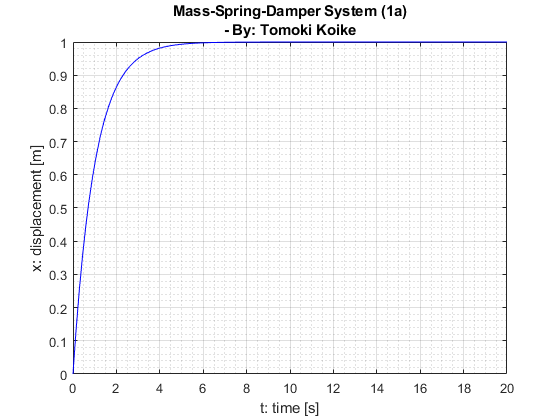

figure(1)
plot(t, x_numer, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Mass-Spring-Damper System (1a)','- By: Tomoki Koike'})
grid on
grid minor
box on 

## 1b.

The analytical solution for this equation is 


$$x\left(t\right)=C_1 +C_2 e^{-2\zeta \omega_n t}$$


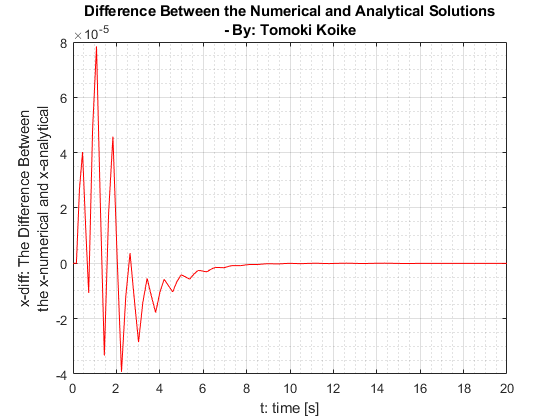

% By applying the initial conditions to the equation above we get that
% C1 = 1/2/zeta/omega and C2 = -1/2/zeta/omega
x_anlyt = 1/2/zeta/omega + -1/2/zeta/omega*exp(-2*zeta*omega*t);
% Taking the difference between x_analytical and x_numerical
x_diff = x_numer - x_anlyt;
% Plotting the 
figure(2)
plot(t, x_diff, '-r')
xlabel('t: time [s]')
ylabel({'x-diff: The Difference Between','the x-numerical and x-analytical'})
title({'Difference Between the Numerical and Analytical Solutions', '- By: Tomoki Koike'})
grid on 
grid minor
box on

#### <ANALYSIS>

#### From the two plots we have made in 1a. and 1b we can see that x-numerical and x-analytical are very identical with the maximum divergence of 8*10^-5, which is almost negligible. This is perhaps due to the computer's usage of limited decimal points during the calculations which alters the final output. However, all in all, the numerical analysis satisfies the theoretical values of the mass-spring-damper system.

## 1c.

If $c=0\;\mathrm{and}\;k<m{\left(\frac{d\theta }{\mathrm{dt}}\right)}^2$, then the equation for the mass-spring-damper system becomes 


$$\overset{\bullet \bullet }{x} \;-{\omega_n }^2 x=0\;\;\;\cdots \left(3\right)$$


Put equation (3) in state variable form

% Solving with ode45
omega = 1; % Setting the omega variable
tspan = [0 20]; % Defining the interval of t
x0 = [1 0]; % Defining the initial conditions 
[t, x] = ode45(@(t,x) fcn2(t,x,omega), tspan, x0); % Solving the ode with ode45
x_numer2 = x(:,1); % Assigning the x_numerical values to a variable

Plotting the result of the solve differential equation 

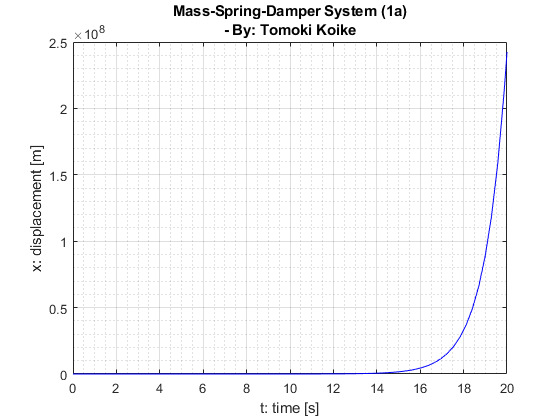

figure(3)
plot(t, x_numer2, '-b')
ylabel('x: displacement [m]')
xlabel('t: time [s]')
title({'Mass-Spring-Damper System (1a)','- By: Tomoki Koike'})
grid on
grid minor
box on 

## 1d.

The analytical solution for this equation is 


$$x\left(t\right)=C_1 e^{\omega_n t} +C_2 e^{-\omega_n t}$$


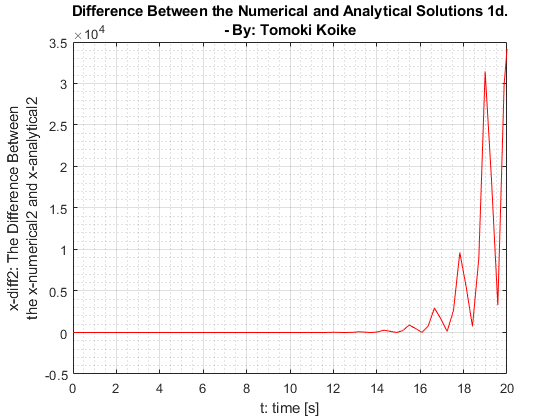

% By applying the initial conditions x(0) = 1 and x`(0) = 0, we get that C1
% = 0.5 and C2 = 0.5.
x_anlyt2 = 0.5*exp(omega*t) + 0.5*exp(-omega*t);
% Taking the difference between x_analytical and x_numerical
x_diff2 = x_numer2 - x_anlyt2;
% Plotting the 
figure(4)
plot(t, x_diff2, '-r')
xlabel('t: time [s]')
ylabel({'x-diff2: The Difference Between','the x-numerical2 and x-analytical2'})
title({'Difference Between the Numerical and Analytical Solutions 1d.', '- By: Tomoki Koike'})
grid on 
grid minor
box on

#### <ANALYSIS>

#### From the plots we can tell that as time, t approaches infinity (or becomes larger) the divergence between the analytical and the numerical solutions become larger. This is perhaps due to dx/dt being different for the two solutions. As you can see in the plot for the difference between the analytical and numerical solutions the divergence also becomes larger as t grows while fluctuating. This suggests that the increase in slope for the two solutions are not the same and either can be greater or smaller. However, if the t-value is small the difference of the two solutions are negligible. 

Creating a function for the differential equation (1a)

function dxdt = fcn(t,x,zeta,omega)
dxdt = zeros(2,1);  % Defining a zero vector to store the dxdt terms 
dxdt(1) = x(2); % Derivative of x1 = x2
dxdt(2) = -2*zeta*omega*x(2); % Derivative of x2 = -2*zeta*omega*x2
end  

Creating a function for the differential equation (1c)

function dxdt = fcn2(t,x,omega)
dxdt = zeros(2,1);  % Defining a zero vector to store the dxdt terms 
dxdt(1) = x(2); % Derivative of x1 = x2
dxdt(2) = omega^2*x(1); % Derivative of x2 = -2*zeta*omega*x2
end 